# Mandelbrot Set & Julia Set

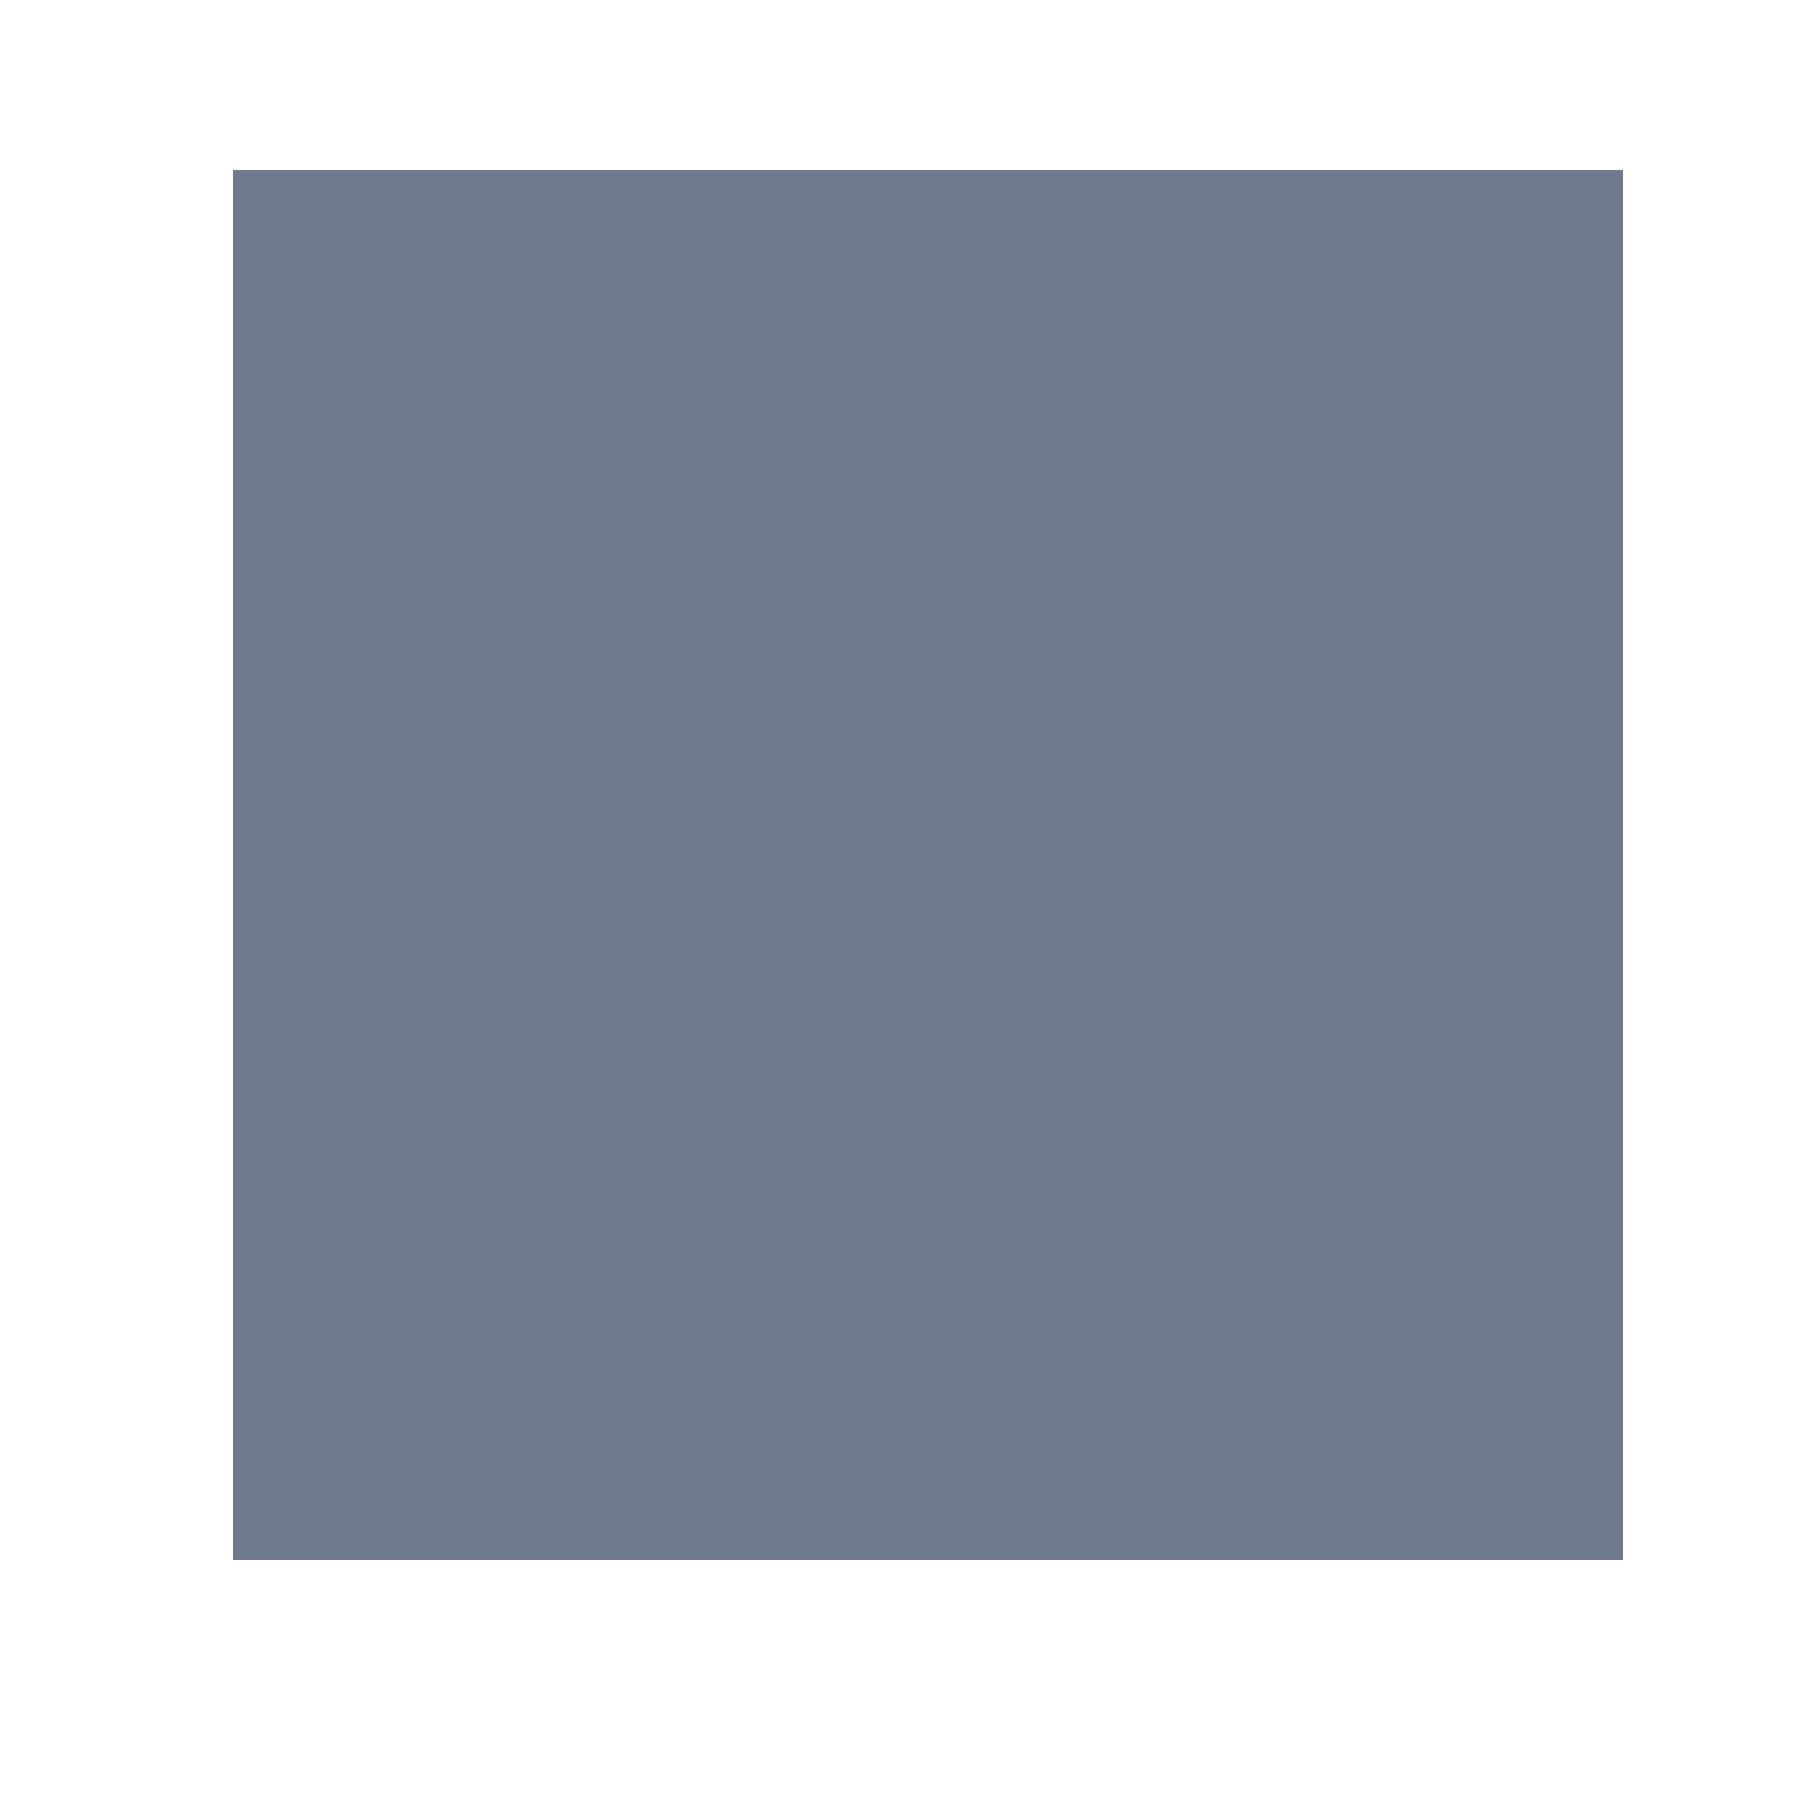

z0_amount =   0.47;
r =          1;
theta = pi * -0.62;
max_iter = 10^ 0.9;
n =           1793;
threshold =   100;
area_init =    1.3;

fig = figure("Position",[0,0,n,n]);

C = r*(cos(theta)+1i*sin(theta));

cla

xlim = [-area, area]+0.1096;
ylim = [-area, area]+0.109;
n = 800;
x = linspace(xlim(1), xlim(2), n);
y = linspace(ylim(1), ylim(2), n);
[xGrid,yGrid] = meshgrid(x,y);

z0 = xGrid + 1i*yGrid;

M = ones(size(z0));
z = z0;
for n = 0:max_iter
    z = z.*z + C + z0*z0_amount;
    inside = abs(z)<=threshold;
    M = M + inside;
end
M = M/max(M,[],"all");

Gsc = M;

cla
imagesc(Gsc);
colormap bone;
pbaspect([1 1 1]);
axis off;
drawnow;

copygraphics(gca,'Resolution',300,"ContentType","image");


imwrite(Gsc,"result.png")

## 参考文献

[1] MathWorks, GPU コンピューティングへの 3 つのアプローチの説明: マンデルブロ集合

[https://jp.mathworks.com/help/parallel-computing/illustrating-three-approaches-to-gpu-computing-the-mandelbrot-set.html](https://jp.mathworks.com/help/parallel-computing/illustrating-three-approaches-to-gpu-computing-the-mandelbrot-set.html)